# Project 2 - Solar Cooker

Gia-uyen Tran and Krishna Suresh

## Question

In remote areas such as the Himalayas, cheap and readily available cooking methods are essential. One such solution is a solar cooker, a paraboloid with a reflective inner surface that harnesses the sun’s energy. 

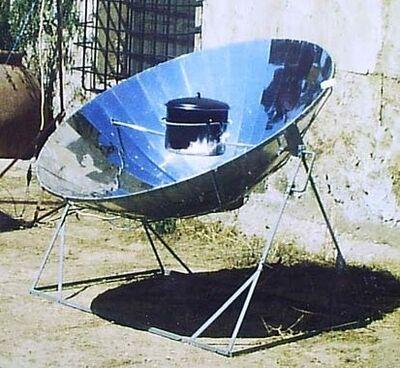

[https://solarcooking.fandom.com/wiki/SK12](https://solarcooking.fandom.com/wiki/SK12)

One property of paraboloids is that when light enters normal to its open circular face, it will always be reflected back to a point called the focus. 

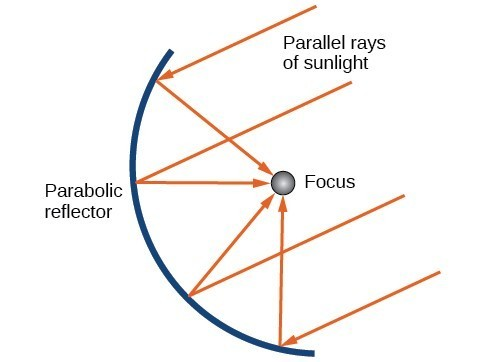

Reflecting properties of parabolas

**Design Question: **

Keeping solar cooker depth constant, what is the minimum radius paraboloid to boil water within a time constant?

This is a design question because it is regarding the variation in parameters that influence the shape of the solar cooker. Our primary motivation behind finding the minimum radius lies with the critical consideration of cost when designing a device to be used by an impoverished region. By minimizing radius we implicitly are looking for the lowest cost solar cooker that can still be feasible for cooking.

## Method

In this model, the sun is the energy source. The sun’s rays are assumed to enter the solar cooker perpendicular to its open circular face and reflect perfectly (i.e. there is no energy loss) off of the paraboloid. Because of the unique properties of a paraboloid, these rays reflect to a point known as the focus, which is where the pot of water will be located. The pot itself is made from 2mm thick stainless steel (this material was chosen because of its abundance and affordability) with an interior diameter of 8cm and height of 8cm. The pot does not have a lid, so the top surface of the water will be exposed. These parameters were chosen to represent a standard small pot. The figure below shows a diagram of the model.

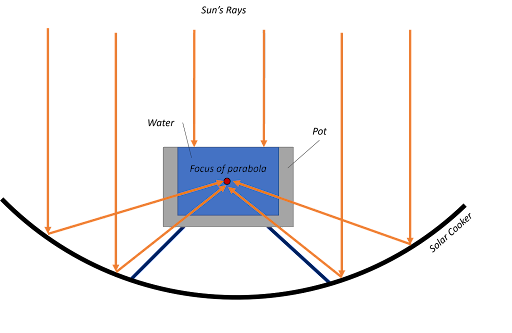

The radiation is reflected off the solar cooker to heat the stainless steel pot via radiation, which then heats the water via convection. The pot itself blocks sunlight from reflecting, but we do not account for that in this model. Furthermore, solar cookers are typically constructed in small segments that collectively resemble the shape of a paraboloid, so they are in reality not an exact continuous parabolic surface. Note that the pot in this model is considered to be one thermal mass, so the conduction between the outer and inner surfaces are not taken into account. 

#### Model Iteration

One iteration we made in our model was to include the heat loss. The system also loses thermal energy through two processes: the convection between the pot and surrounding air in addition to the convection between the exposed water and surrounding air. Additionally, note that the heat loss due to evaporation is not represented in this model. 

## Stock and Flow Diagram

[STOCK and FLOW HERE]

In order to represent this model mathematically, we used a few fundamental equations relating to heat transfer. The following variables have been adjusted to reflect the environmental impacts of a Himalayan setting (altitude = 3000m). The weather was assumed to be static, environmental factors such as changes in temperature, clouds that obscure sunlight, and the possibility of wind were not accounted for.

## Mathematical Representation

## Programmatic Representation 

This process can be modeled with the function solar_cooker_sim, which takes the radius of a paraboloid as its input and outputs three things:

- T, a vector with the times chosen by ode45

- M, a matrix with columns for the temperature of the pot (column 1) and the water (column 2) at each timestep

- boil_time, the  time in minutes that it would take for that solar cooker to bring the water in the pot to a boil (363 K).

The solar_cooker_sim function uses a rate function to represent the change in energy of the pot and water. Then uses ode45 to estimate the function value over time and finally output the time the water reaches the boiling point.

Example solar cooker with a radius of 0.6 meters simulated over 120 minutes:

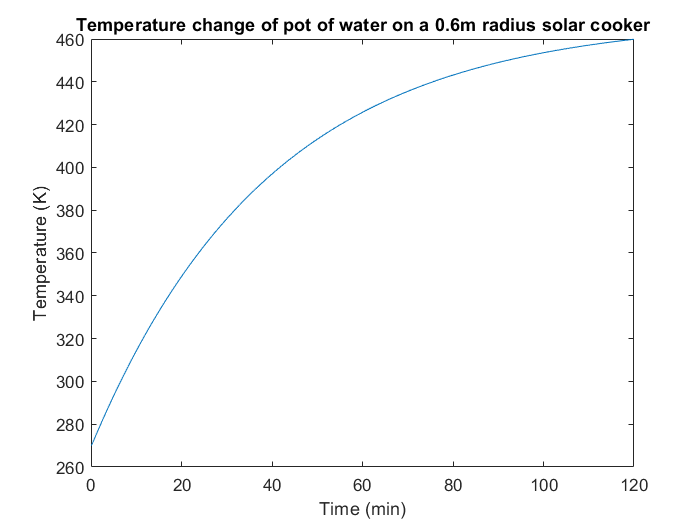

clf
[T, M, boil_time] = solar_cooker_sim(0.6); % simulate the change in temp of water and the pot over 120 minutes
plot(T, M(:,2))
ylabel("Temperature (K)")
xlabel("Time (min)")
title("Temperature change of pot of water on a 0.6m radius solar cooker")

[Radiation eqn] indicates that the projected area of the parabola is significant. Differing depths with the same radius would have the same projected area, so it would not impact the total energy from radiation. Consequently, this model holds depth as a constant 0.5 meters (chosen to be relatively proportional to the radius sweep) while changing radius.

#### Parameter Sweep

We can now parameter sweep radius values. The radii values were chosen such that the focus was at most half a meter above the largest circular cross section of the paraboloid. The intention was to model a reasonable solar cooker design. While it would be possible to have a focus further out, it would become increasingly difficult to build a stable platform to hold the pot. Additionally, the focus was at least 10 centimeters away from the bottom of the cooker to ensure that the pot (8cm tall) would fit. With these guidelines in mind, the radius values were swept ranging from 0.5m to 1.5m incrementing by 0.01m each time.

clear
sweep_range=0.5:0.01:5; % range of radius to sweep across
J = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
    [T, M, boil_time] = solar_cooker_sim(sweep_range(i)); % simulate for a specific radius
    J(i,:) = [sweep_range(i), boil_time];
end
J % Data relating radius and time to boil

J =     0.5000   43.4269
    0.5100   40.4714
    0.5200   37.9454
    0.5300   35.7368
    0.5400   33.7613
    0.5500   31.9028
    0.5600   30.2337
    0.5700   28.7373
    0.5800   27.3489
    0.5900   26.0830


## Material Cost of Solar Cooker

In order to find the material cost of a solar cooker, we first abstracted the volumetric shape of a paraboloid shell to a two dimensional surface. This corresponds to a cost calculation of sheets being per square meter. Using this abstraction, we calculated the surface area of the paraboloid by rotating a parabola around the y axis. 

### Finding Material Cost of Solar Cooker

In order to find the material cost of a solar cooker, we first abstracted the volumetric shape of a paraboloid shell to a two dimensional surface. This corresponds to a cost calculation of sheets being per square meter. Using this abstraction, we calculated the surface area of the paraboloid by rotating a parabola around the y axis. 


$$$$r= \text{radius of paraboloid} $$
$$h= \text{height of paraboloid} $$
$$  \int_{-r}^{r} 2 \pi x \,ds  $$
$$ ds = \sqrt{1 + \left(\frac {dy} {dx}\right)^2} $$
Points which the parabola passes through:
$$(0,0), (-r, h), (r, h)$$
$$ 0 = a(0)^2 + b(0)+c $$
$$ c = 0 $$
$$ h = a(r)^2 + b(r)+c $$
$$ h = a(-r)^2 + b(-r)+c $$
$$2h = 2ar^2 $$
$$ a = h/r^2 $$
$$ y = \frac {h} {r^2} x^2$$
$$ \frac {dy} {dx} = \frac {2h} {r^2} x$$
$$ ds = \sqrt{1 + \left(\frac {2h} {r^2} x\right)^2}$$
$$  \int_{0}^{r} 2 \pi x \, \sqrt{1 + \left(\frac {2h} {r^2} x\right)^2} dx  $$
$$


The *paraboloid_radius_to_cost* function numerically calculates this integral to find the inner surface area of the solar cooker from 3 parameters:

- Radius in meters

- Depth of solar cooker in meters

- Cost per square meter in dollars

It then multiplies this area by the cost per square meter to find an approximate cost to produce each paraboloid. 

Cost per square meter

Through research of common solar cooker reflective materials we found that mylar is a standard surface with a high reflectivity. The estimated cost in US dollars per square meter is 1.5 (amazon citation).

cost_per_sq_m = 1.5 % in $/m^2

cost_per_sq_m = 1.5000

Below is a sweep displaying this relationship between cost and radius of the solar cooker, but we will only be using this to find the cost of one solar cooker. This cost is representative of the surface material, but we are treating the rest of the solar cooker as a proportional cost to this surface material cost.

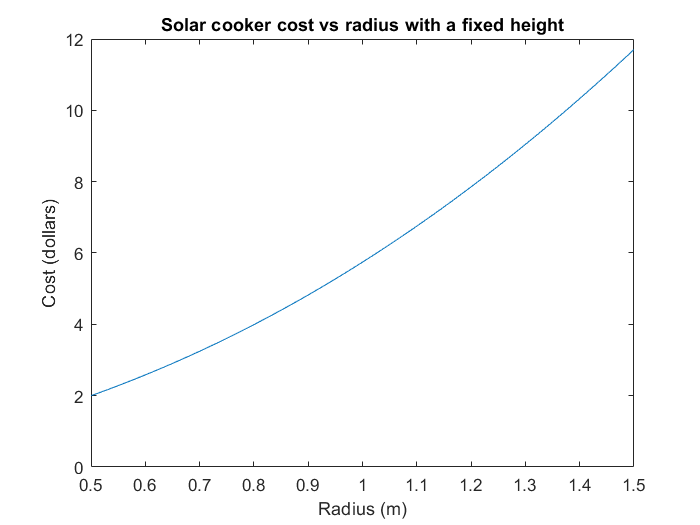

figure(3)
sweep_range=0.5:0.01:1.5; % sweep range
K = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
     cost = paraboloid_radius_to_cost(sweep_range(i), 0.5, cost_per_sq_m); % finding cost of a paraboloid for a specific radius and fixed height 
     K(i,:) = [sweep_range(i), cost];
end
plot(K(:,1), K(:,2))
xlabel("Radius (m)")
ylabel("Cost (dollars)")
title("Solar cooker cost vs radius with a fixed height")

## Results

figure(2)
sweep_range=0.5:0.01:1.5; % sweep range
K = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
    [T, M, boil_time] = solar_cooker_sim(sweep_range(i)); % simulation with a specfic radius
    K(i,:) = [sweep_range(i), boil_time];
end
time_constrain = 15;
[min_time, min_radius_ind] = min(K(1:find(K(:,2) < time_constrain, 1),2)); % finding the radius which boils water closest to 15 minutes
min_radius = K(min_radius_ind,1)

min_radius = 0.7400

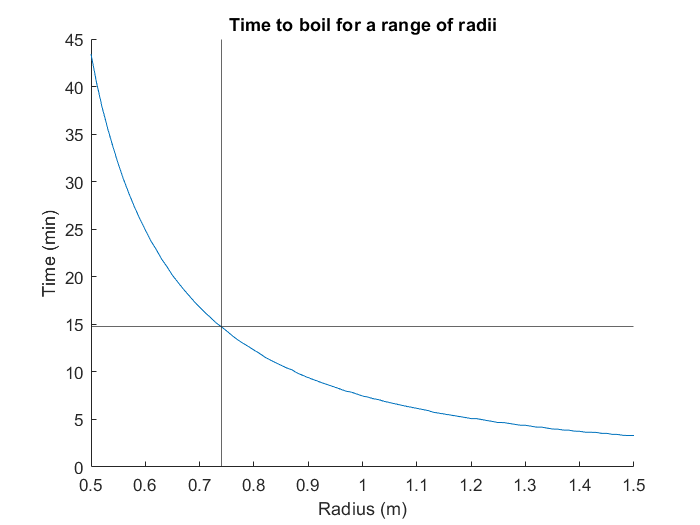

clf
hold on
plot(K(:,1), K(:,2))
xline(min_radius);
yline(min_time);
xlabel("Radius (m)")
ylabel("Time (min)")
title("Time to boil for a range of radii")

The above sweep across radii illustrates the change in time to boil as we increase the radius of the solar cooker. With a time constraint of 15 minutes, a solar cooker with a radius of X meters is the minimum size to heat water to a temperature of 363 K. However, we do find that as we lower our time constraint the change in radius dramatically increases with incremental temperature changes. Therefore, our representation of the relationship between time to boil and radius is only relevant in the ranges leading up to the asymptotic end condition of the model.

Next, we applied the conversion between radius and predicted cost to find a dollar amount of $3.53 calculated from the surface area of the solar cooker. 

cost = paraboloid_radius_to_cost(min_radius, 0.5, cost_per_sq_m)

cost = 3.5337

## Interpret

Overall, our results indicate water boiling times that fit the realm of reasonability and indicate a trend that is similar to the asymptotic diminishing returns we inferred would occur. Some key considerations that we found to break our representation of this system include the evaporation of water, reflection efficiency, and pot conduction. Since water will change phase at the point of boiling and carry away energy through the molecules leaving the mass, the carrying capacity of heat is much lower than what our model displays when run over long periods of time. Additionally, our assumption of perfect reflection of radiation skews our boiling times to be faster than with a physical test. Finally, we assumed a uniform heat distribution with energy flow into the pot which would more likely follow a model including conduction between the outer and inner surfaces. But, for the purposes of estimating a radius to optimally boil water within a fixed time interval, these factors more so influence the long term or proportional impacts. Therefore, our findings illustrating the non-linear relationship between time to boil and radius of a solar cooker through the high level abstraction of heat flows can effectively find the minimum cost of a solar cooker to boil water within 15 minutes.

#### References